clc; clear; close all;

% Parámetros del sistema
V_pfr = 200*10; % Volumen del PFR en litros
n = 15; % Número de CSTR en serie
V_cstr = V_pfr / n; % Volumen de cada CSTR

% Constantes de reacción
k = 0.1; % Constante cinética de primer orden
E_a = 215000; % Energía de activación en J/mol
R = 8.314; % Constante de los gases en J/(mol*K)
T_ref = 1100; % Temperatura de referencia en Kelvin

% Flujo de entrada
F_A = 1354458; % Flujo inicial de A en mol/h
F_B = 145120; % Flujo inicial de B en mol/h

% Matrices de estado para n CSTR en serie
A = -k * eye(n);
B = (1/V_cstr) * ones(n,1);
C = ones(1,n); % Ajuste de la salida para compatibilidad
D = 0;

% Crear función de transferencia del sistema
sys = ss(A, B, C, D);
G = tf(sys);

% Mostrar función de transferencia sin control
disp('Función de transferencia sin control:');

Función de transferencia sin control:


G

G =
 
  0.1125 s^14 + 0.1575 s^13 + 0.1024 s^12 + 0.04095 s^11 + 0.01126 s^10 + 0.002252 s^9 + 0.0003378 s^8 + 3.861e-05 s^7 + 3.378e-06 s^6 + 2.252e-07 s^5 + 1.126e-08 s^4 + 4.095e-10 s^3 + 1.024e-11 s^2 + 1.575e-13 s + 1.125e-15
  ------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
      s^15 + 1.5 s^14 + 1.05 s^13 + 0.455 s^12 + 0.1365 s^11 + 0.03003 s^10 + 0.005005 s^9 + 0.0006435 s^8 + 6.435e-05 s^7 + 5.005e-06 s^6 + 3.003e-07 s^5 + 1.365e-08 s^4 + 4.55e-10 s^3 + 1.05e-11 s^2 + 1.5e-13 s + 1e-15
 
Continuous-time transfer function.


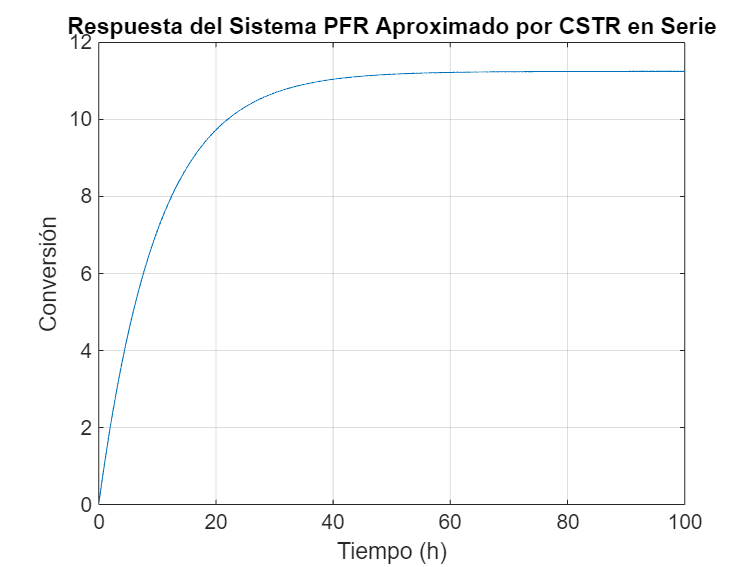


% Representación en el tiempo
t = linspace(0, 100, 1000); % Tiempo en horas
u = ones(size(t)); % Entrada escalón
[y, t_out] = lsim(G, u, t);

% Gráfica de respuesta en el tiempo
figure;
plot(t_out, y*10);
xlabel('Tiempo (h)'); ylabel('Conversión');
title('Respuesta del Sistema PFR Aproximado por CSTR en Serie');
grid on;

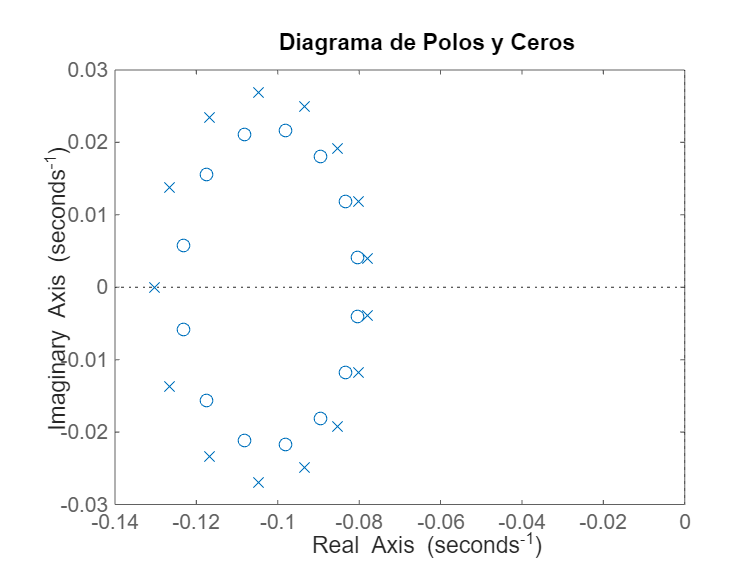


% Diagrama de polos y ceros
figure;
pzmap(G);
title('Diagrama de Polos y Ceros');


% Sintonización del control PID para conversión
Kp = 100; Ki = 25; Kd = 0.1; % Ajuste para estabilización en 0.8
PID = pid(Kp, Ki, Kd);
G_PID = feedback(PID * G, 1, -1); % Ajuste para compatibilidad de tamaños

% Mostrar función de transferencia con control PID
disp('Función de transferencia con control PID:');

Función de transferencia con control PID:


G_PID

G_PID =
 
  0.01125 s^16 + 11.27 s^15 + 18.57 s^14 + 14.18 s^13 + 6.656 s^12 + 2.15 s^11 + 0.5068 s^10 + 0.09009 s^9 + 0.01231 s^8 + 0.001303 s^7 + 0.000107 s^6 + 6.757e-06 s^5 + 3.225e-07 s^4 + 1.126e-08 s^3 + 2.717e-10 s^2 + 4.05e-12 s + 2.813e-14
  ---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  1.011 s^16 + 12.77 s^15 + 19.62 s^14 + 14.63 s^13 + 6.792 s^12 + 2.18 s^11 + 0.5118 s^10 + 0.09074 s^9 + 0.01237 s^8 + 0.001308 s^7 + 0.0001073 s^6 + 6.77e-06 s^5 + 3.229e-07 s^4 + 1.127e-08 s^3 + 2.718e-10 s^2 + 4.051e-12 s + 2.813e-14
 
Continuous-time transfer function.


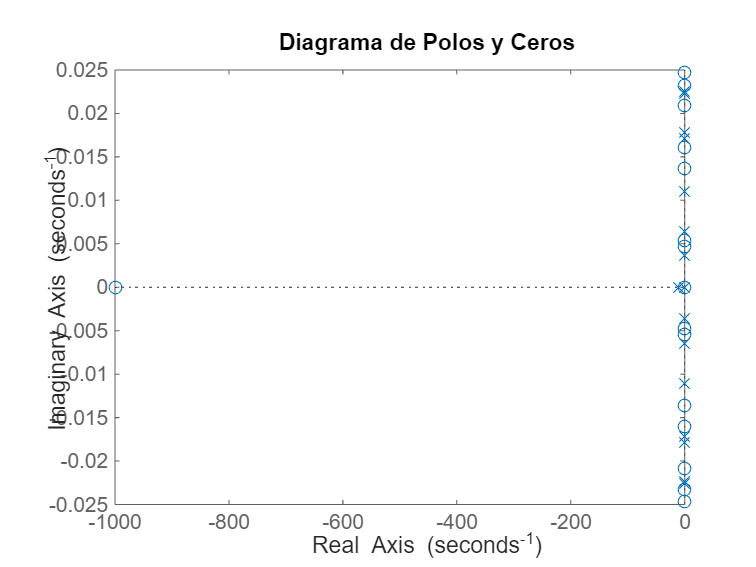

pzmap(G_PID);
title('Diagrama de Polos y Ceros');

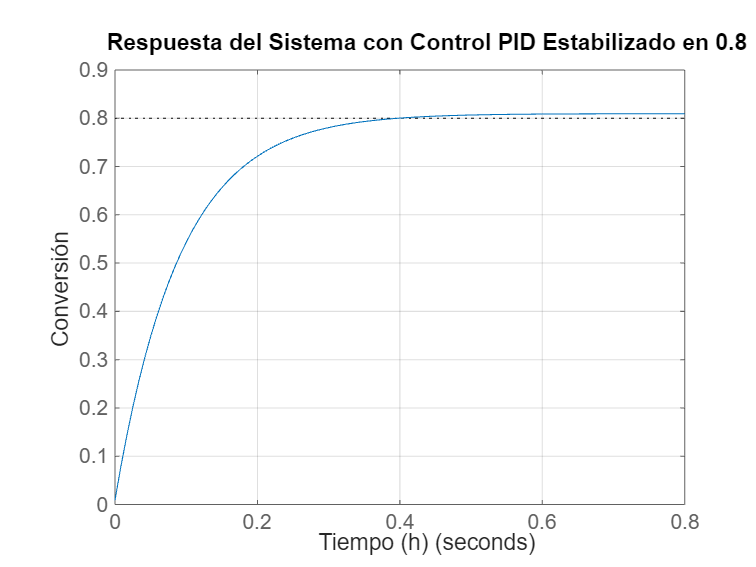


% Respuesta del sistema en lazo cerrado
y_target = 0.8; % Objetivo de estabilización
figure;
step(y_target * G_PID);
title('Respuesta del Sistema con Control PID Estabilizado en 0.8');
xlabel('Tiempo (h)'); ylabel('Conversión');
grid on;

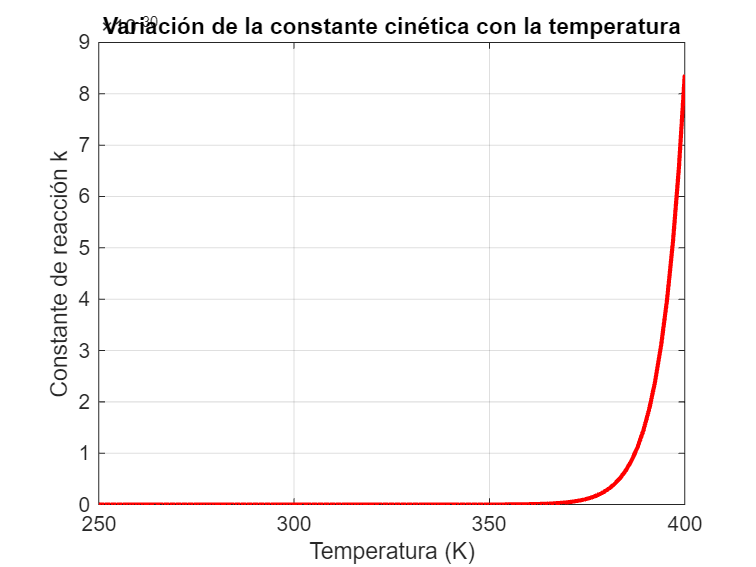


% Control de temperatura basado en ecuaciones termodinámicas y cinéticas
T = linspace(250, 400, 100); % Rango de temperaturas en Kelvin
k_T = k * exp(-E_a ./ (R * T)); % Variación de la constante cinética con la temperatura

figure;
plot(T, k_T, 'r', 'LineWidth', 2);
xlabel('Temperatura (K)'); ylabel('Constante de reacción k');
title('Variación de la constante cinética con la temperatura');
grid on;

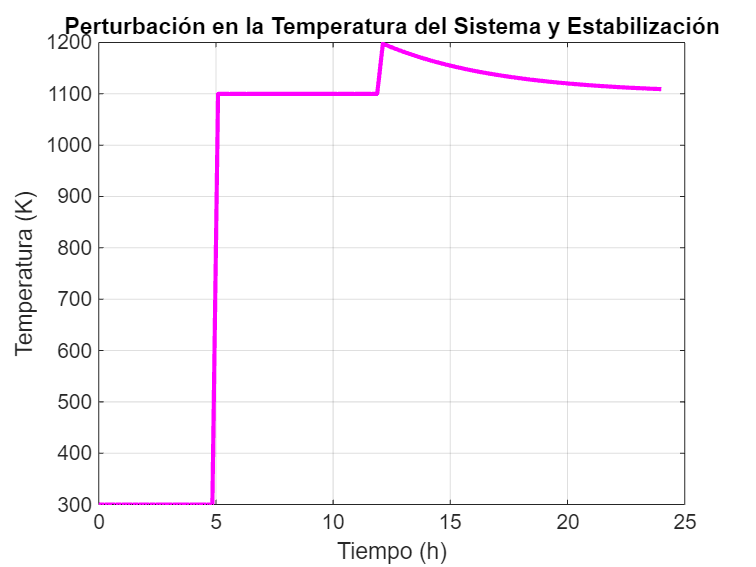


% Perturbaciones en la temperatura
t_temp = linspace(0, 24, 100);
T_var = T_ref * ones(size(t_temp));
T_var(t_temp < 5) = 300; % Temperatura ambiente inicial

% Inserción de perturbación en la temperatura
t_pert = 12; % Tiempo en horas en que ocurre la perturbación
mag_pert = 100; % Magnitud de la perturbación en Kelvin
T_var(t_temp >= t_pert) = T_ref + mag_pert * exp(-(t_temp(t_temp >= t_pert) - t_pert) / 5);

figure;
plot(t_temp, T_var, 'm', 'LineWidth', 2);
xlabel('Tiempo (h)'); ylabel('Temperatura (K)');
title('Perturbación en la Temperatura del Sistema y Estabilización');
grid on;

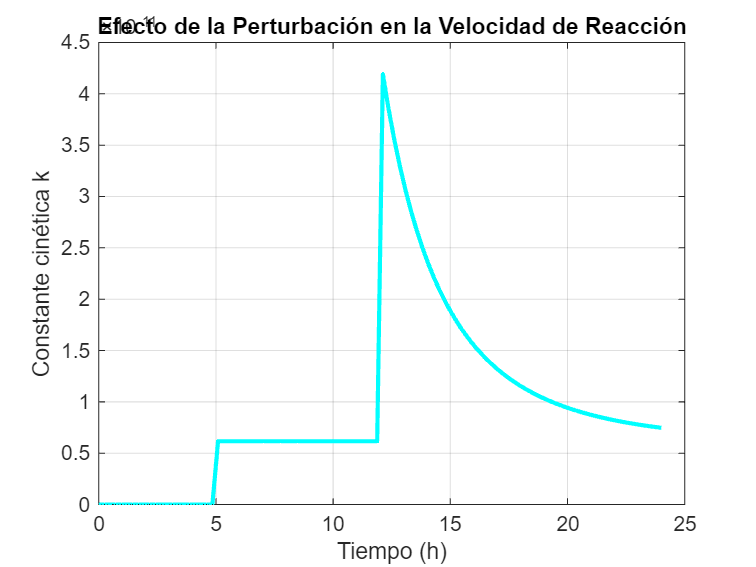


% Efecto de la temperatura en la velocidad de reacción
k_pert = k * exp(-E_a ./ (R * T_var));

figure;
plot(t_temp, k_pert, 'c', 'LineWidth', 2);
xlabel('Tiempo (h)'); ylabel('Constante cinética k');
title('Efecto de la Perturbación en la Velocidad de Reacción');
grid on;